Thursday, July 19th

Author: Joseph Greene

Email: joeg18@bu.edu

Recipient: Professor Lei Tian

      *  Computational and Optical Approaches to Reducing Autoflourescence in the         *

*                                           Boston University Miniscope*

**Section 1: Problem definition**

    The impedus of the Brain Interface Initiative has led to a rapidly growing need for open source solutions designed to monitor neural circuit functions and assist researchers in spurring evolution in neural imaging technologies. In response to this void, Boston University's Gardner group developed a single-photon, wirelessly controlled, light-weight (1.8g) microscopy system entitled the 'finchscope' in the hopes of producing a solution which allows the most amount of freedom for monitored animals [1]. The 'finchscope', or it's more generic name the 'miniscope', images neural activity by detecting genetically encoded calcium deposites in the brain, which responds with green photons when a neuron fires and incident light excites the calcium. This allows researchers to resolve neural activity in small rodents in a much finer scale then previously possible. 

    However, since the utilized indiciator is omnipresent throughout the brain, the miniscope is bombarded with a high background signal due to incident light as well as constant neural activity triggering irrelevant reactions (autoflourescence). This results in a low-varying background signal obvious in the raw data (shown below) which needs to be computationally removed to easily distinquish the desired activity. The point of this report is to investigate optical or computational solutions to remove this background in the hopes of making the miniscope a more robust, and universally applicable tool.

%Autoflourescence in raw data
raw = VideoReader('raw1.mov');
% currAxes = axes;
% while raw.CurrentTime <= 30
%     vidFrame = readFrame(raw);
%     image(vidFrame, 'Parent', currAxes);
%     currAxes.Visible = 'off';
%     pause(1/raw.FrameRate);
% end

%%Define functions
F = @(x) fftshift(fft2(ifftshift(x)));
iF = @(x) fftshift(ifft2(ifftshift(x)));

    First I will discuss a potential optical solution through an optical hilbert transform, then discuss limiting the background though a computational solution.

**Section 2: Optical Hilbert Transform**

    The Hilbert Transform (HT) is a spatial or temporal transform which keeps the input signal in it's beginning domain (i.e spacial -> spacial or spatial frequency (s.frequency) -> s.frequency). In the spatial domain, it is defined as shifting the frequencies by $\frac{\lambda }{4}$ abd in the s.frequency domain it has a -90 degree phase shift in the spectral components. Or, in other words, the hilbert transform is convolution with the kernel $\frac{1}{\pi^2 \left(xy\right)}$ in the spatial domain or multiplying by -j*signum(u)*-j*signum(v) in the s.frequency domain. One of the benefit of taking the hilbert transform is we may use it to generate the analytic signal (AS, a representation of the signal suppressing the negative frequency components of the fourier transform). It has been shown that taking the 1D Hilbert transform in each dirction of a 2D image may as an alternative to conventional edge detection methods, like analyzing the laplacian [2]. The method utilized in [2] suggests utilizing the hilbert transform of a gaussian function as a quasi-biorthogonal wavelet. 

    However, several sources have investigated implementing a 2D hilbert transform designed to produce a more refined edge detection/filtering operation [3,4]. Normally, a 2D hilbert transform is just the 1D hilbert transform extended on the x and y. As described in [3], this only supports the AS in one quandrant of the image. 

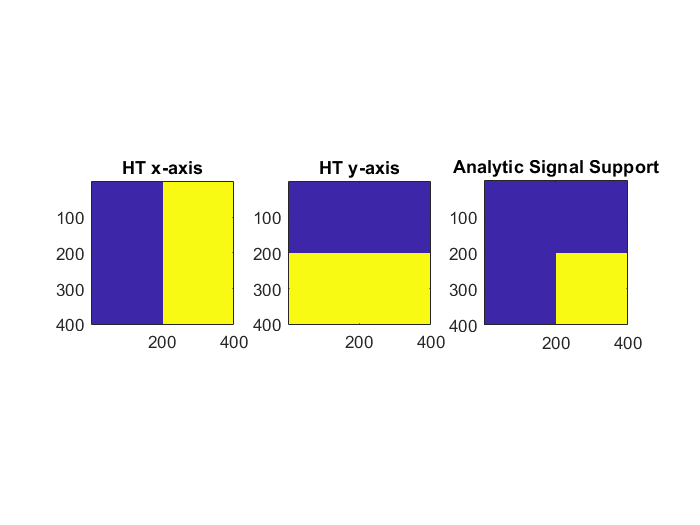

N = 400;
[xx,yy] = meshgrid(-N/2:N/2-1);
figure
subplot(1,3,1)
imagesc(sign(xx))
title('HT x-axis')
axis('square')
subplot(1,3,2)
imagesc(sign(yy))
title('HT y-axis')
axis('square')
subplot(1,3,3)
imagesc((1+sign(xx)).*(1+sign(yy)))
title('Analytic Signal Support')
axis('square')

    To combat this issue, [3] suggests utilizing a directional hilbert transform, where the signum operators are redefined as follows:


$$\begin{array}{l}
\text{                              }1,\text{ }\text{ }0\text{ }<x\le \frac{N}{2}-1\\
signc\left(x\right)=\text{ }0,\text{ }\text{ }\text{ }x=0\text{ }\text{or}\text{ }\frac{N}{2}\\
\text{                         }-1,\text{ }\frac{N}{2}+1<x\le N-1
\end{array}$$


    The above definition, where signc represents signum-combined and N represents the dimension of an NxN image, thus orients the hilbert transform along the line y=x and may also be slightly adjusted to aline along y=-x. This gives better coverage for the hilbert transform and corresponding analytic signal.

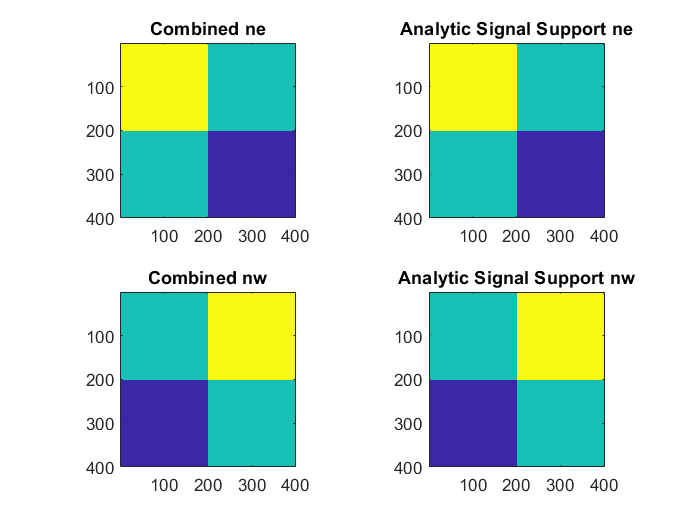

%Use outside function to generate new directional meshgrids (entitled n1,n2)
[n1,n2] = Signc2(N);
%Note there is a scale factor of 1i in each of the combined hilbert transform formulas,
%that I omit due to matlab only plotting a real signal with imagesc(). The AS does not have 1i.
figure
subplot(2,2,1)
imagesc(1/2*(n1+n2))
title('Combined ne') %Mesh of support alined along northeast of grid
axis('square')
subplot(2,2,2)
imagesc(1+1/2*(n1+n2))
title('Analytic Signal Support ne')
axis('square')
subplot(2,2,3)
imagesc(1/2*(-n1+n2))
title('Combined nw') %Mesh of support alined along northwest of grid
axis('square')
subplot(2,2,4)
imagesc(1+1/2*(-n1+n2))
title('Analytic Signal Support nw')
axis('square')

    Obviously, the two vectors n1,n2 are othogonal so reconstructing a signal decomposed into these bases follows the triangle inequality -> ie the combined hilbert transform of an image (Ihc) may be described by Ine and Inw:


$$I_{HC} =||I_{ne} +I_{nw} ||$$


    This yields a final coverage of:

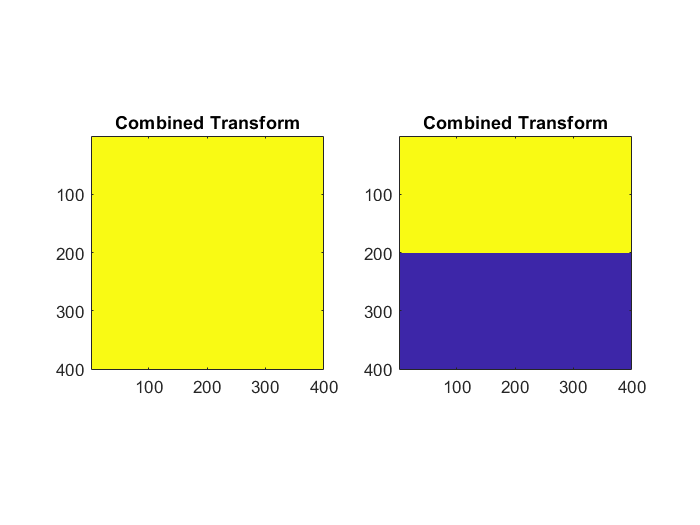

figure
subplot(1,2,1)
imagesc(abs(abs(1/2*(n1+n2))+(1/2*(-n1+n2))))
title('Combined Transform')
axis('square')
subplot(1,2,2)
imagesc(abs(abs(1+1/2*(n1+n2))+(1+1/2*(-n1+n2))))
title('Combined Transform')
axis('square')

    To analyze the effects of the traditional hilbert transform vs the combined hilbert transform, I will first apply each to a generic object and superficially observe each's edge detection capacities.

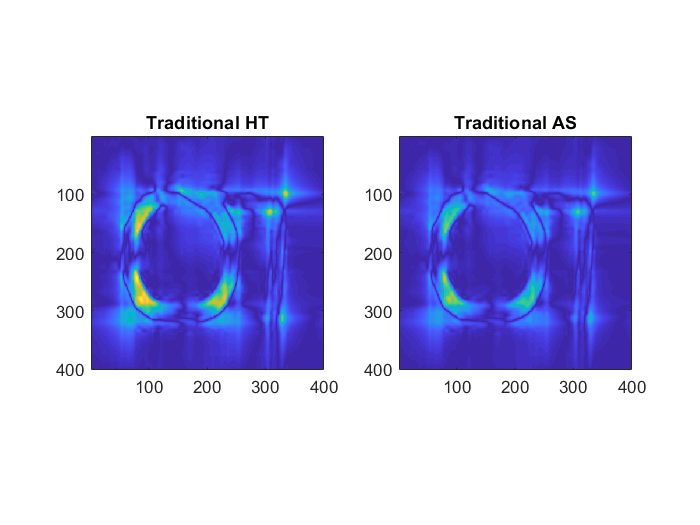

o1 = imread('5_obj.png');
o1 = imresize(im2double(rgb2gray(o1)),[N,N]);
%Traditional HT
o1Hil = iF(-1*sign(xx).*sign(yy).*F(o1));
o1AS = iF(1-1i*sign(xx).*sign(yy).*F(o1));

figure
subplot(1,2,1)
imagesc(abs(o1Hil))
title('Traditional HT')
axis('square')
subplot(1,2,2)
imagesc(abs(o1AS))
title('Traditional AS')
axis('square')

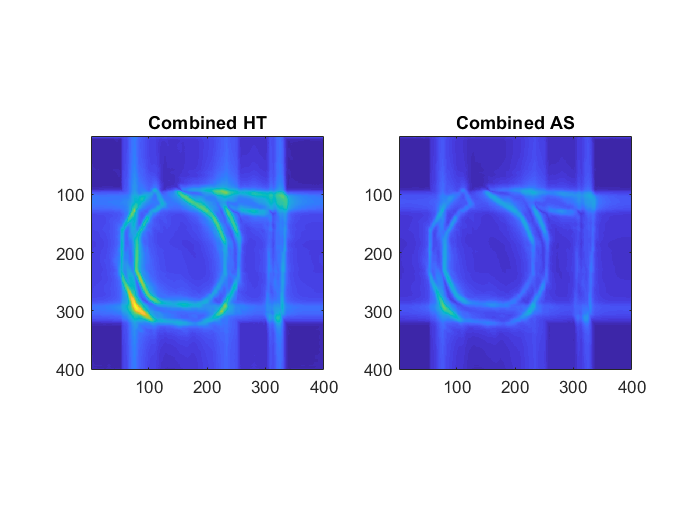

%Combined HT
Ine = iF(-1/2*1j*(-n1+n2).*F(o1));
Inw = iF(-1/2*1j*(n1+n2).*F(o1));
Iasne = iF(1+1/2*(-n1+n2).*F(o1));
Iasnw = iF(1+1/2*(n1+n2).*F(o1));

Ihc = abs(abs(Ine)+abs(Inw));
Ias = abs(abs(Iasne)+abs(Iasnw));
figure
subplot(1,2,1)
imagesc(Ihc)
title('Combined HT')
axis('square')
subplot(1,2,2)
imagesc(Ias)
title('Combined AS')
axis('square')

    Evidently the combined HT produces a more consistent edge detection then the traditional HT. Now lets observe how each affects raw data.

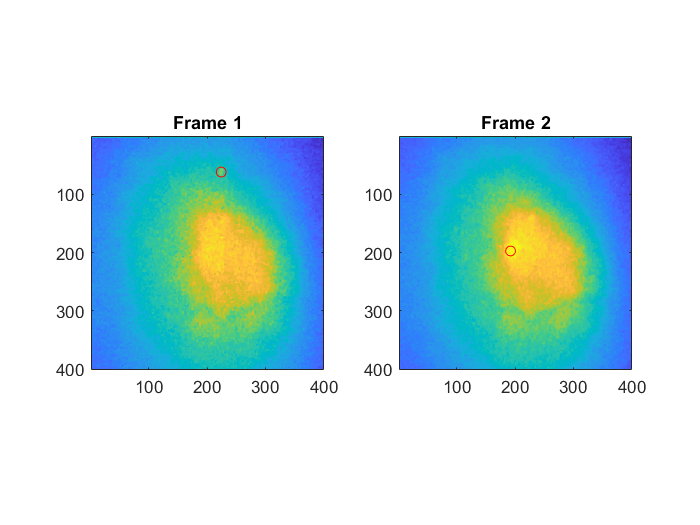

%First Practice Spot (Away from central/high noise)
raw.CurrentTime = 10.6; %Spot Upper Left
x1 = [round(0.55*N):round(0.57*N)]; %x coodinates of spot
y1 = [round(0.1375*N):round(0.17*N)]; %y coodinates of spot
frame1 = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);

%Second Practice Image (In high noise in center)
raw.CurrentTime = 6.9; %Center Spot
x2 = [round(0.455*N):round(0.505*N)]; %x coordinates
y2 = [round(0.46*N):round(0.525*N)]; %y coodinates
frame2 = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);

figure
subplot(1,2,1)
imagesc(frame1)
hold on
plot(mean(x1),mean(y1),'ro')
hold off
title('Frame 1')
axis('square')
subplot(1,2,2)
imagesc(frame2)
hold on
plot(mean(x2),mean(y2),'ro')
hold off
title('Frame 2')
axis('square')

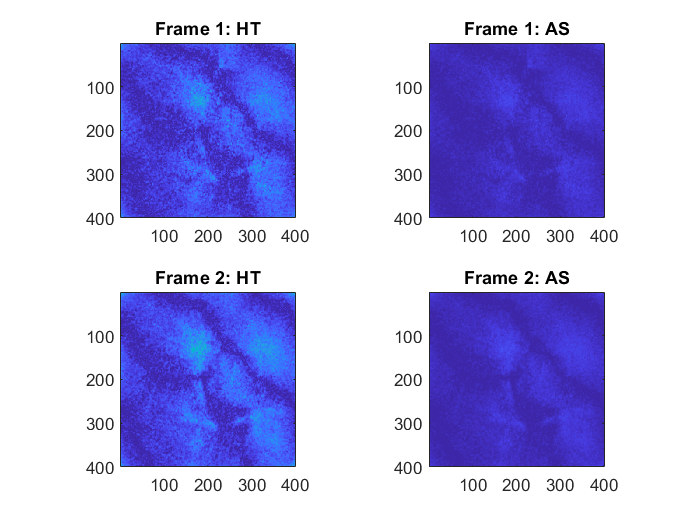

%Traditional
frame1Hil = iF(-1*sign(xx).*sign(yy).*F(frame1));
frame1AS = iF(1-1i*sign(xx).*sign(yy).*F(frame1));
frame2Hil = iF(-1*sign(xx).*sign(yy).*F(frame2));
frame2AS = iF(1-1i*sign(xx).*sign(yy).*F(frame2));

figure
subplot(2,2,1)
imagesc(abs(frame1Hil))
title('Frame 1: HT')
axis('square')
subplot(2,2,2)
imagesc(abs(frame1AS))
title('Frame 1: AS')
axis('square')
subplot(2,2,3)
imagesc(abs(frame2Hil))
title('Frame 2: HT')
axis('square')
subplot(2,2,4)
imagesc(abs(frame2AS))
title('Frame 2: AS')
axis('square')

    Clearly the traditional HT does a superb job of filtering much of the noise but also removes our desired signals as well! Let's observe how the combined HT performs.

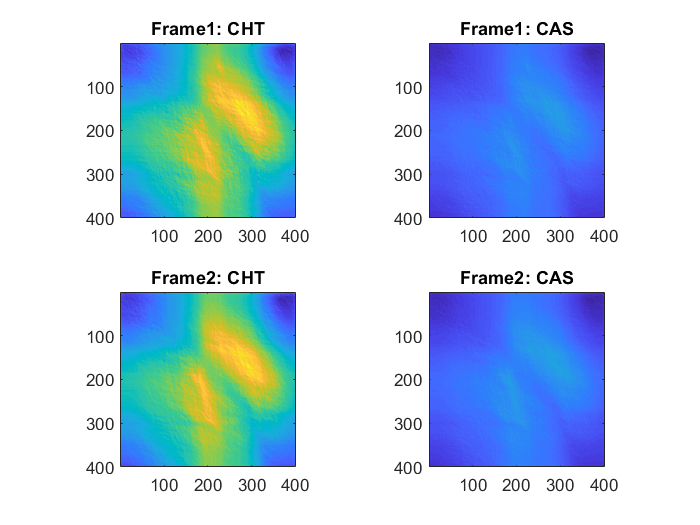

Ine = iF(-1/2*1j*(-n1+n2).*F(o1));
Inw = iF(-1/2*1j*(n1+n2).*F(o1));

Iframe1hc = abs(abs(iF(-1/2*1j*(-n1+n2).*F(frame1)))+abs(iF(-1/2*1j*(n1+n2).*F(frame1))));
Iframe1as = abs(abs(iF(1+1/2*(-n1+n2).*F(frame1)))+abs(iF(1+1/2*(n1+n2).*F(frame1))));
Iframe2hc = abs(abs(iF(-1/2*1j*(-n1+n2).*F(frame2)))+abs(iF(-1/2*1j*(n1+n2).*F(frame2))));
Iframe2as = abs(abs(iF(1+1/2*(-n1+n2).*F(frame2)))+abs(iF(1+1/2*(n1+n2).*F(frame2))));

figure
subplot(2,2,1)
imagesc(Iframe1hc)
title('Frame1: CHT')
axis('square')
subplot(2,2,2)
imagesc(Iframe1as)
title('Frame1: CAS')
axis('square')
subplot(2,2,3)
imagesc(Iframe2hc)
title('Frame2: CHT')
axis('square')
subplot(2,2,4)
imagesc(Iframe2as)
title('Frame2: CAS')
axis('square')

    Unforunately, we have the same result, where the CTH and CAS perserve more of the original signal, but do not assist in removing background from the image -> and even risk removing the signal we are looking for!

**Section 3: Computational Approach**

   In this following section, I will attempt to reduce the background section through a computational approach. Specifically, I will apply the following procedure:


$$I_{new} ={|I}_{frame} -I_0 |M$$


    Where Inew is the resulting image, Iframe is the new frame, I0 is an image where no neuron is firing, and M is a boolean operator that sets any pixel below the value of mean(${|I}_{\text{frame}} -I_0 |$) to 0. This technique will effectively remove the low varying noise and leave only the variation between images.

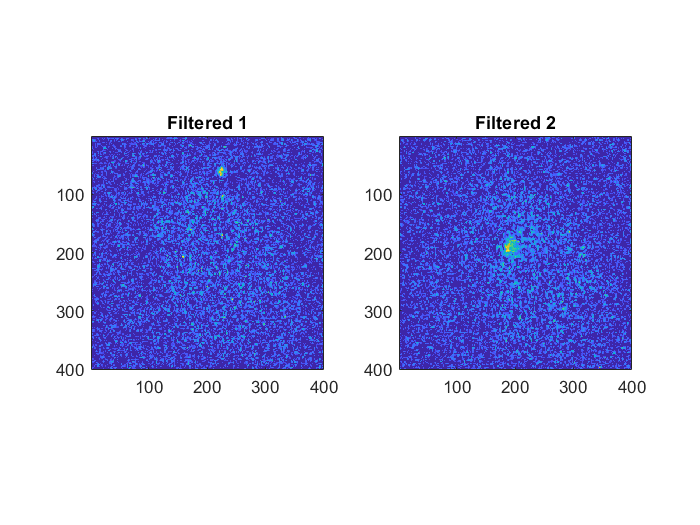

raw.CurrentTime = 0;
blankFrame = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);
norm1 = abs(frame1-blankFrame);
norm1(norm1<mean(norm1(:))) = 0;
norm2 = abs(frame2-blankFrame);
norm2(norm2<mean(norm2(:))) = 0;
figure
subplot(1,2,1)
imagesc(norm1./max(norm1(:)))
title('Filtered 1')
axis('square')
subplot(1,2,2)
imagesc(norm2./max(norm2(:)))
title('Filtered 2')
axis('square')

    Clearly this method is more effective at retaining the beginning signal. To justify the improvement in this computational model, I will determine the signal-to-background ratio (SBR) by averaging the intensity of the spot pixels divited by the average background and compare the SBR values for the original image, optically adjusted image and computational image.

sbr01 = mean2(frame1(y1,x1))/mean2(frame1)

sbr01 = 1.2279

sbrOptics1 = mean2(Iframe1hc(y1,x1))/mean2(Iframe1hc)

sbrOptics1 = 1.1692

sbrComp1 = mean2(norm1(y1,x1))/mean2(norm1)

sbrComp1 = 7.3050


sbr02 = mean2(frame2(y2,x2))/mean2(frame2)

sbr02 = 1.7280

sbrOptics2 = mean2(Iframe2hc(y2,x2))/mean2(Iframe2hc)

sbrOptics2 = 1.1939

sbrComp2 = mean2(norm2(y2,x2))/mean2(norm2)

sbrComp2 = 5.4471

    Evidently, computationally reducing the background greatly increases the SBR, while applying just the hilbert transform actually blurs our signal, reducing the SBR. In the next section, I will explore alternative methods to increase the SBR even more by only using a single image and a reference.

**Section 3: Combined Approach**

    Before diving blindly into altenate approaches, let's investigate the fourier domain expressions of the original image vs the computationally filtered image. This will assist us in building intuition into the nature of the remaining noise.

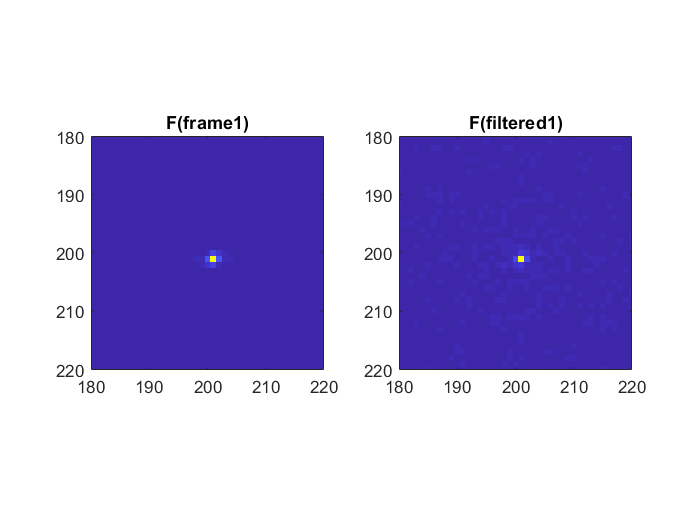

figure
subplot(1,2,1)
imagesc(abs(F(frame1)))
title('F(frame1)')
axis([N/2-20 N/2+20 N/2-20 N/2+20])
axis('square')
subplot(1,2,2)
imagesc(abs(F(norm1)))
title('F(filtered1)')
axis([N/2-20 N/2+20 N/2-20 N/2+20])
axis('square')

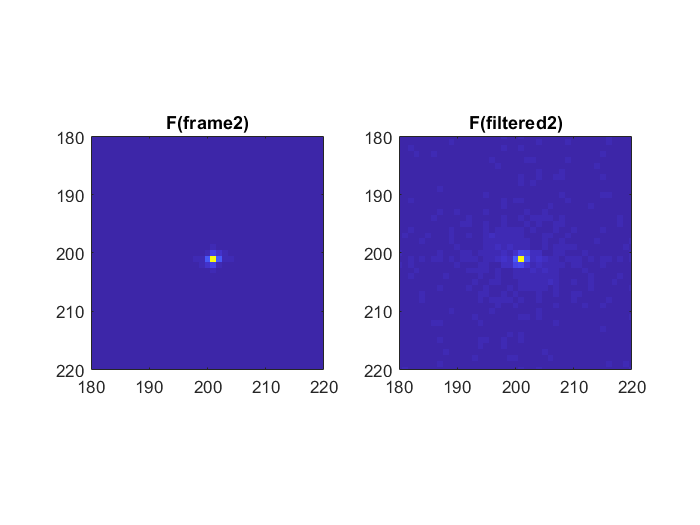


figure
subplot(1,2,1)
imagesc(abs(F(frame2)))
title('F(frame2)')
axis([N/2-20 N/2+20 N/2-20 N/2+20])
axis('square')
subplot(1,2,2)
imagesc(abs(F(norm2)))
title('F(filtered2)')
axis([N/2-20 N/2+20 N/2-20 N/2+20])
axis('square')

    Intuitively, it makes sense that the fourier domain of the filtered image is hectic, as I set several pixels to 0 in the midst of a noisy image. Either way, both fourier domains rely heavily on low frequency components and have occassional, low magnitude high frequency components. Much of the present noise must be contained in the high frequency componenets, as the noise is dense, and fluctuates with high varients. So by preserving the low frequency components and either optically or computationally removing the high frequencies should 'blur out' the noise, preserving the slower varying neural spots. Below represents the result of that filtering after some trial and error performed outside this report. Note the DC componenet ilocated at (M+1,M+1).

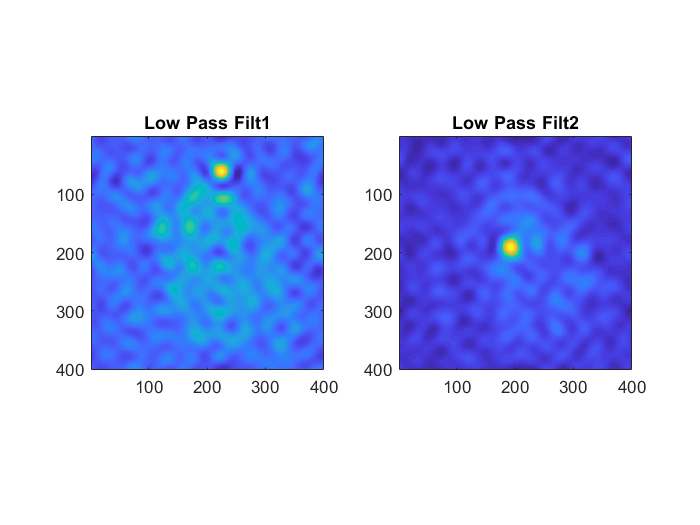

filt = zeros(N,N);
delta = N/2-190;
filt(N/2+1-delta:N/2+1+delta,N/2+1-delta:N/2+1+delta) = 1;%Tightly contained around dc center
xprime1 = round(0.535*N):round(0.585*N);
yprime1 = round(0.1075*N):round(0.1925*N);
xprime2 = round(0.445*N):round(0.51*N);
yprime2 = round(0.42*N):round(0.5275*N);

frame1lp = abs(iF(F(norm1).*filt));
frame2lp = abs(iF(F(norm2).*filt));

figure
subplot(1,2,1)
imagesc(frame1lp)
title('Low Pass Filt1')
axis('square')
subplot(1,2,2)
imagesc(frame2lp)
title('Low Pass Filt2')
axis('square')


sbrlp1 = mean2(frame1lp(yprime1,xprime1))/mean2(frame1lp)

sbrlp1 = 2.6186

sbrlp2 = mean2(frame2lp(yprime2,xprime2))/mean2(frame2lp)

sbrlp2 = 4.3537

    Note, while the SBR is technically lower in this case, that is only based off my definition of SBR, where I average the entire background instead of the immediate background around a neuron. Also, this makes sense because removing the high frequency data will spread out the energy of a firing neuron throughout the image. However, visually the image appears better under these conditions as it's easier to resolve the firing neuron. I will produce brief .avi files using both filtering techniques as demos.

%Video with removed background
raw.CurrentTime = 0;
m1 = VideoWriter('output_removed_background.avi');
open(m1)
while(raw.CurrentTime <=30)
    frame = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);
    norm = abs(frame-blankFrame);
    norm(norm<mean(norm(:))) = 0;
    writeVideo(m1,(norm./max(norm(:))))
end
close(m1)
% 
% %Removed background, lpf
% raw.CurrentTime = 0;
% m2 = VideoWriter('output_lpf.avi');
% open(m2)
% while(raw.CurrentTime <=30)
%     frame = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);
%     norm = abs(frame-blankFrame);
%     norm(norm<mean(norm(:))) = 0;
%     rec = abs(iF(F(norm).*filt));
%     writeVideo(m2,(rec./max(rec(:))))
% end
% close(m2)

% %Removed background,lpf,combined hilbert transform
% raw.CurrentTime = 0;
% m3 = VideoWriter('output_lpf_cht.avi');
% open(m3)
% while(raw.CurrentTime <=30)
%     frame = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);
%     norm = abs(frame-blankFrame);
%     norm(norm<mean(norm(:))) = 0;
%     con = abs(iF(F(norm).*filt));
%     writeVideo(m3,(con./max(con(:))))
% end
% close(m3)

% %For reference uses, video with JUST combined HT
% raw.CurrentTime = 0;
% ref = VideoWriter('output_ref_cht.avi');
% open(ref)
% while(raw.CurrentTime <=30)
%     frame = imresize(im2double(rgb2gray(readFrame(raw))),[N,N]);
%     norm = abs(frame-blankFrame);
%     norm(norm<mean(norm(:))) = 0;
%     con = conv2(norm,kernel);
%     writeVideo(ref,(con./max(con(:))))
% end
% close(ref)

Section X: References

[1] *An open source, wireless capable miniature microscope system*, William A Liberti et all, 2017

[2] *One-Dimensional Processing for Edge Detection using Hilbert Transform*, B. Yegnanarayana et all

[3] *An Approach to the 2D Hilbert Transform for Image Processing Applications*, Juan V. Lorenzo-Ginori, 2010

[4] *2D Image Analysis by Generalized Hilbert Transforms in Conformal Space*, Gerald Sommer